# **FSIM (Functional SIMulator)**

**per ****f-HDGM**** e ****fp-HDGM**

Parametri da impostare:

- $\rho \ [1\times1]$;

- $\mathbf{c}_{\epsilon} \ [p_{\epsilon}\times 1]$;

- 
$$\mathbf{C}_{\beta} \ [b\times p_{\beta}]$$


- $\Sigma_0 \ [n\cdot p_z\times n\cdot p_z]$;

- $\mathbf{\mu}_0 \ [n\cdot p_z\times 1]$;

- $\mathbf{G} \ [p_z\times p_z]$;

- 
$$\mathbf{V} \ [p_z\times p_z]$$


- $\mathbf{\theta} \ [p_z\times 1]$;

- $n$, $q$, $b$ e $T$

clear all
clc
rng('default')

#### **Scelta dei punti**

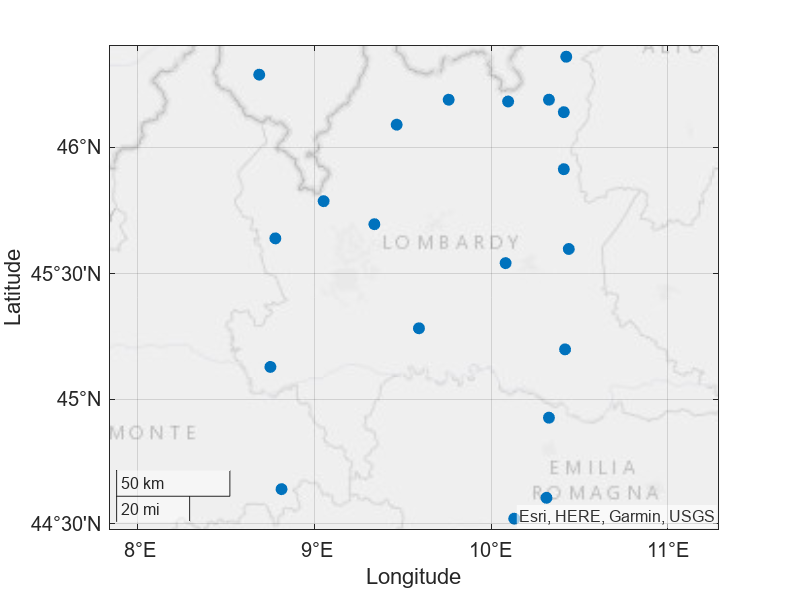

n = 20;
points = FSIM.get_points(n);
geoscatter(points, "Latitude", "Longitude", "filled")

#### Impostazione dei parametri

rng('default')

q = 24;
T = 365;
params.rho = 10;
n_basis.p_eps = 5;
n_basis.p_beta = 7;
n_basis.p_z = 7;

b = 2;
X = cell(T, 1);
for t=1:T
    X_t = ones(q*n, 2);
    for i=2:b
        X_t(:, 2) = randi(100, q*n, 1);
    end
    X{t} = X_t;
end

obj = FSIM(points, q, T, "NumBasis", n_basis, "Parameters", params);

FSIM (Functional SIMulator)
 
Authors: 
- Lorenzo LEONI
- Nicola ZAMBELLI
 
Dimensions: 
- n, q, b and T: [20 24 1 365]
- p_eps, p_beta and p_z: [5 7 7]
 
Parameters set: 
- rho: 10
- c_eps: [21   -0.0664489    -0.193816      1.22426    -0.304687]
- c_beta_1: [46  25  49  33  56  64  59]
- diag_G: [0.45398     0.50623     0.63056     0.20169     0.20303     0.16564     0.94144]
- diag_V: [2  5  5  2  8  7  8]
- theta: [36  36  36  36  36  36  36]


#### Avvio della/e simulazione/i

obj = obj.run(10);